# **200664P _  A4**

## Part 1

## Q1

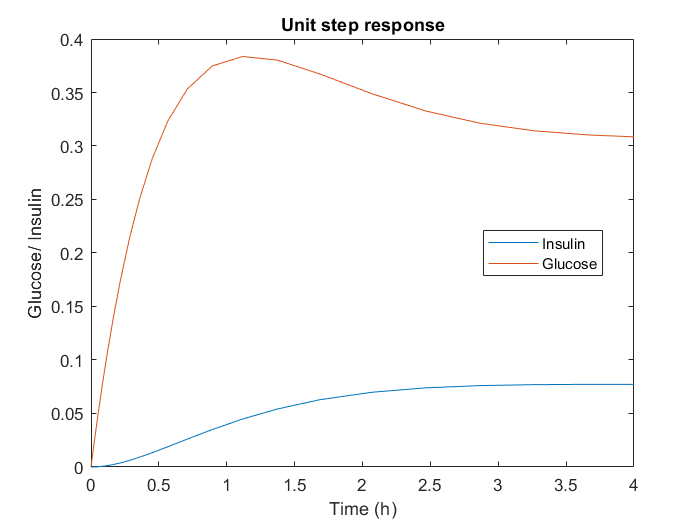

[t,y] = ode23('unit_step',[0, 4],[0, 0] );
plot(t,y);
legend('Insulin','Glucose',"Location","best");
xlabel('Time (h)');
ylabel('Glucose/ Insulin');
title('Unit step response');

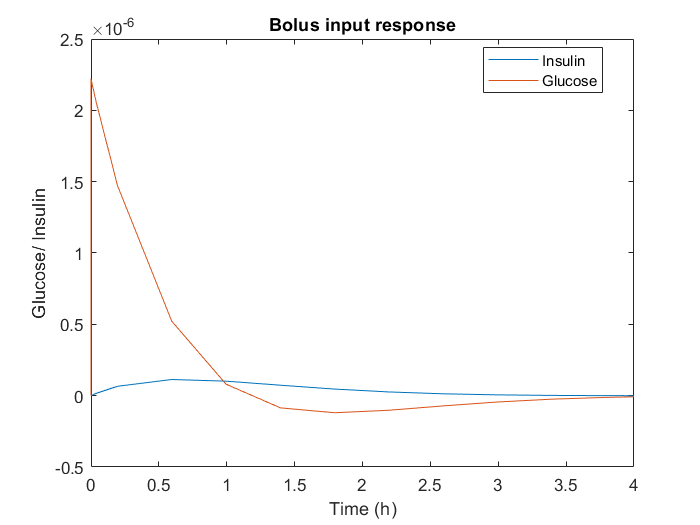

[t,y] = ode23('bolus',[0, 4],[0, 0] );
plot(t,y);
legend('Insulin','Glucose',"Location","best");
xlabel('Time (h)');
ylabel('Glucose/ Insulin');
title('Bolus input response');

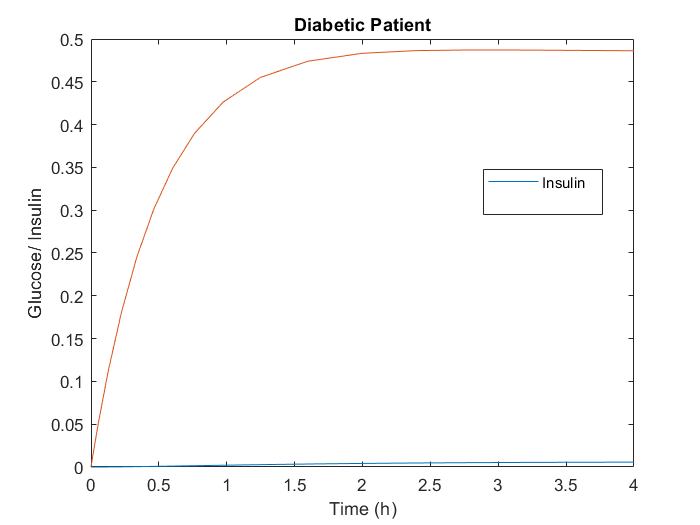

[t,y] = ode23('diabetic',[0, 4],[0, 0] );
plot(t,y);
legend('Insulin','Glucose',"Location","best");
xlabel('Time (h)');
ylabel('Glucose/ Insulin');
title('Diabetic Patient');

[t,y] = ode23('diabetic_insulin',[0, 4],[0, 0] );
plot(t,y);
legend('Insulin','Glucose',"Location","best");
xlabel('Time (h)');
ylabel('Glucose/ Insulin');
title('Diabetic Patient with Insulin');

## Q2

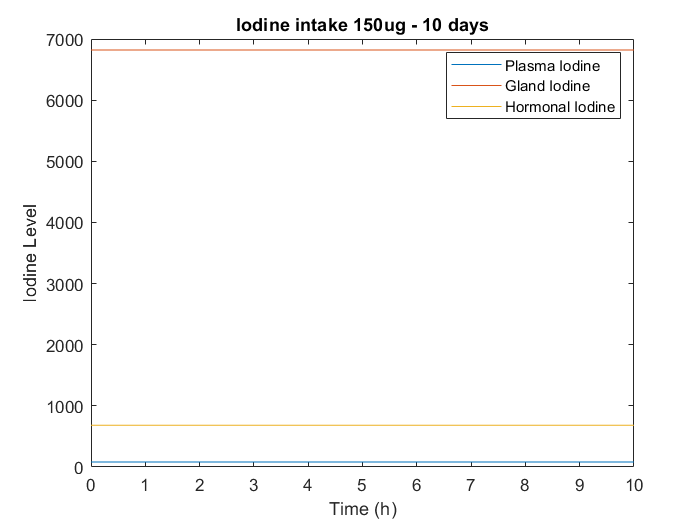

[t,y] = ode23('iodine_150',[0 10],[81.2 6821 682]);
plot(t,y)
legend ('Plasma Iodine','Gland Iodine','Hormonal Iodine')
xlabel('Time (h)');
ylabel('Iodine Level');
title('Iodine intake 150ug - 10 days');

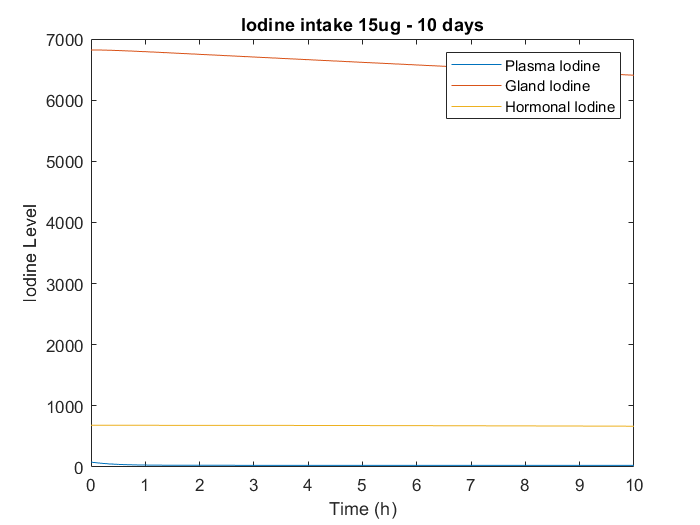

[t,y] = ode23('iodine_15',[0 10],[81.2 6821 682]);
plot(t,y)
legend ('Plasma Iodine','Gland Iodine','Hormonal Iodine')
xlabel('Time (h)');
ylabel('Iodine Level');
title('Iodine intake 15ug - 10 days');

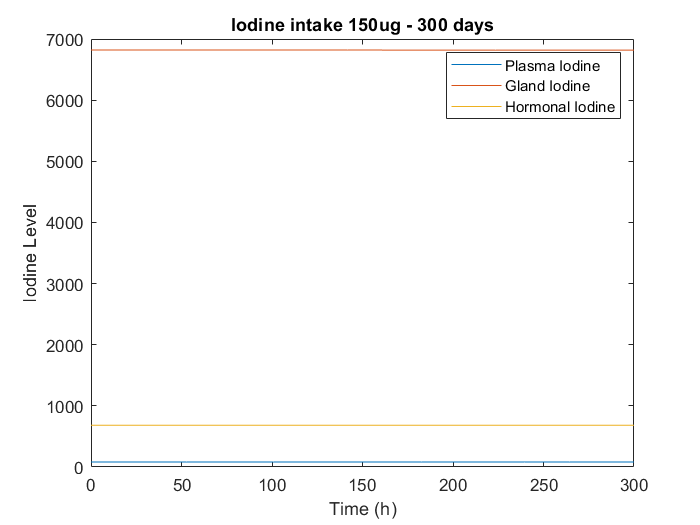

[t,y] = ode23('iodine_150',[0 300],[81.2 6821 682]);
plot(t,y)
legend ('Plasma Iodine','Gland Iodine','Hormonal Iodine')
xlabel('Time (h)');
ylabel('Iodine Level');
title('Iodine intake 150ug - 300 days');

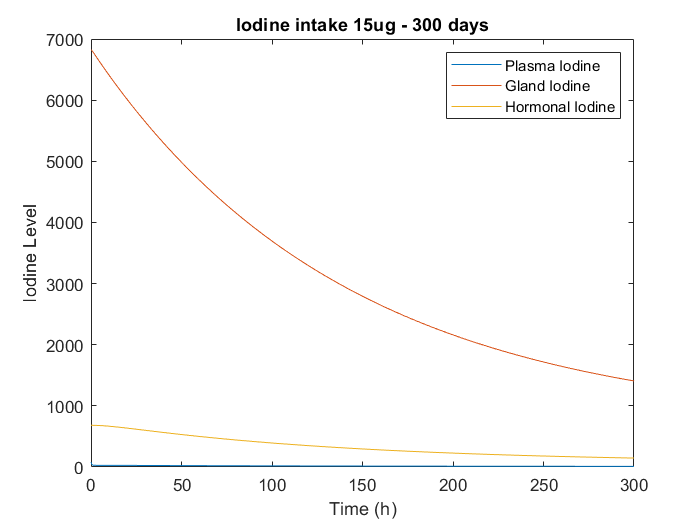

[t,y] = ode23('iodine_15',[0 300],[81.2 6821 682]);
plot(t,y)
legend ('Plasma Iodine','Gland Iodine','Hormonal Iodine')
xlabel('Time (h)');
ylabel('Iodine Level');
title('Iodine intake 15ug - 300 days');

## a)

In this condition, the immune system mistakenly attacks and damages the thyroid gland, leading to reduced production of thyroid hormones. In the Riggs' model, the effects of autoimmune thyroid disease affects the k2 parameter, as it controls the level of gland thyroid of the body. We will set it to 0.005 from 0.01.

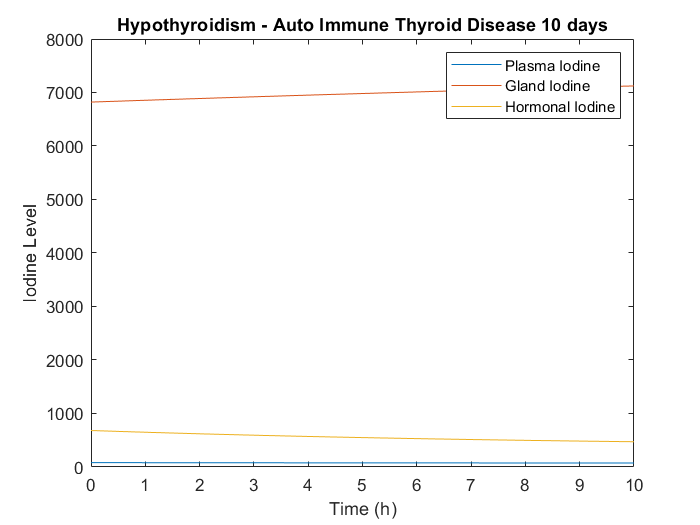

[t,y] = ode23('iodine_a',[0 10],[81.2 6821 682]);
plot(t,y)
legend ('Plasma Iodine','Gland Iodine','Hormonal Iodine')
xlabel('Time (h)');
ylabel('Iodine Level');
title('Hypothyroidism - Auto Immune Thyroid Disease 10 days');

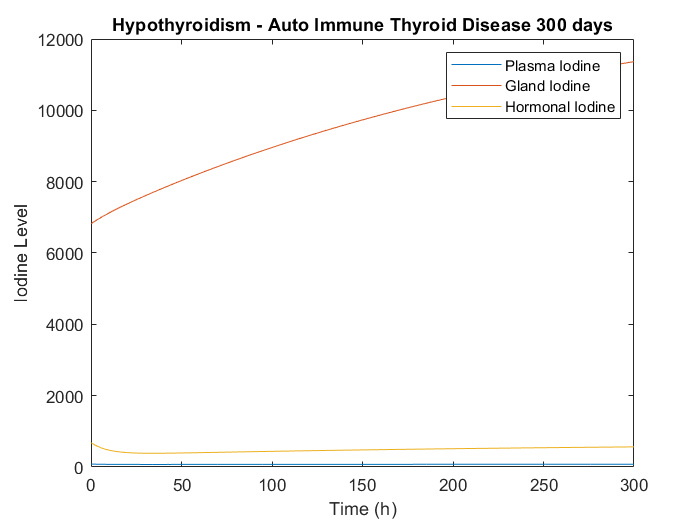

[t,y] = ode23('iodine_a',[0 300],[81.2 6821 682]);
plot(t,y)
legend ('Plasma Iodine','Gland Iodine','Hormonal Iodine')
xlabel('Time (h)');
ylabel('Iodine Level');
title('Hypothyroidism - Auto Immune Thyroid Disease 300 days');

The amount of iodine in the thyroid gland has increased. But we can see now the plasma iodine and hormonal iodine levels have dropped because of the weakening of the production of thyroid hormone.

## b)

Insufficient iodine intake prevents the thyroid gland from producing adequate amounts of thyroid hormones. In the Riggs' model, the effects of low iodine intake can be simulated by reducing the intake of Iodine by reducing the B1(t).

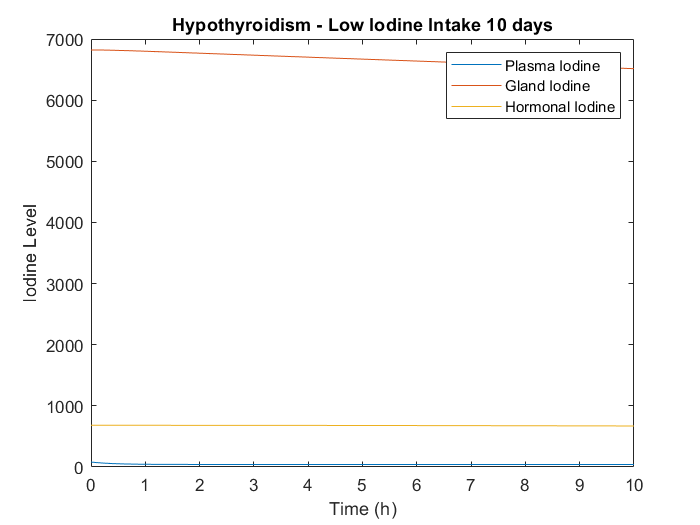

[t,y] = ode23('iodine_b',[0 10],[81.2 6821 682]);
plot(t,y)
legend ('Plasma Iodine','Gland Iodine','Hormonal Iodine')
xlabel('Time (h)');
ylabel('Iodine Level');
title('Hypothyroidism - Low Iodine Intake 10 days');

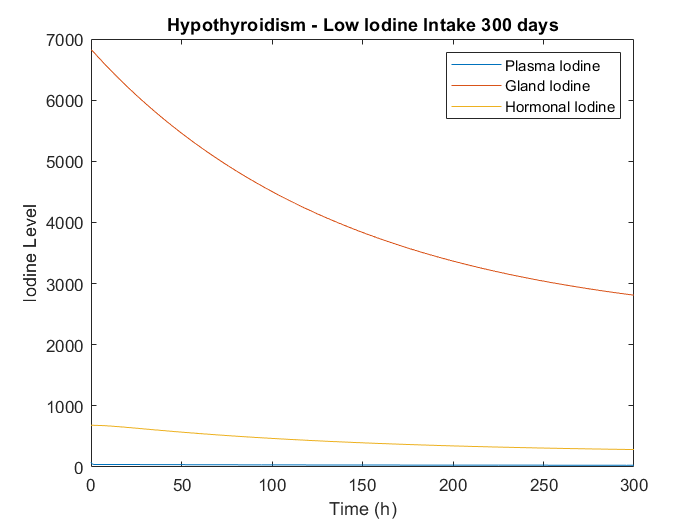

[t,y] = ode23('iodine_b',[0 300],[81.2 6821 682]);
plot(t,y)
legend ('Plasma Iodine','Gland Iodine','Hormonal Iodine')
xlabel('Time (h)');
ylabel('Iodine Level');
title('Hypothyroidism - Low Iodine Intake 300 days');

The reduction of Iodine intake reduces the overall Iodine levels of the body, as it mitigates the thyroid hormone production. 

## c)

Grave's disease is characterized by excessive production of thyroid hormones. In this condition, the immune system produces antibodies that stimulate the thyroid gland to overproduce hormones. In the Riggs' model, the effects of Grave's disease can be simulated by increasing the value of k2(t).

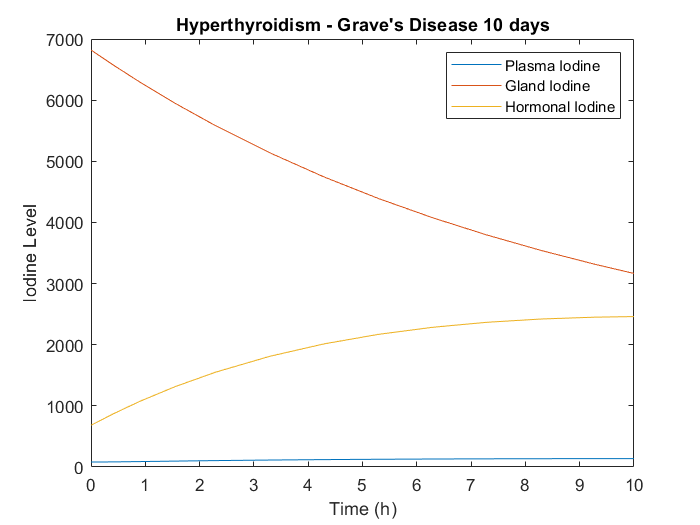

[t,y] = ode23('iodine_c',[0 10],[81.2 6821 682]);
plot(t,y)
legend ('Plasma Iodine','Gland Iodine','Hormonal Iodine')
xlabel('Time (h)');
ylabel('Iodine Level');
title("Hyperthyroidism - Grave's Disease 10 days");

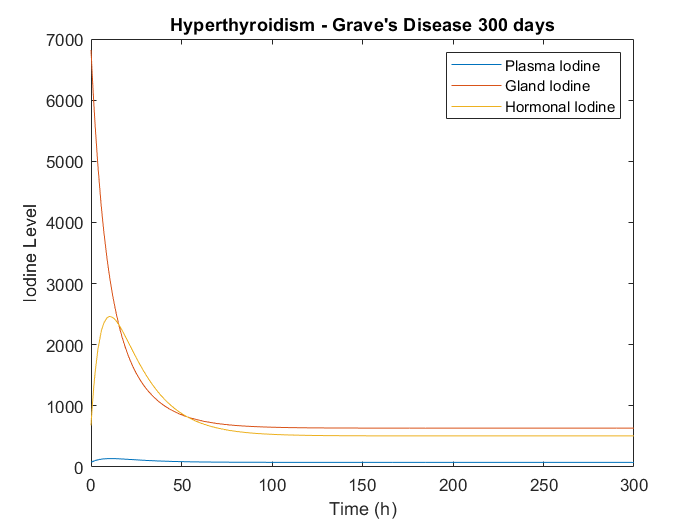

[t,y] = ode23('iodine_c',[0 300],[81.2 6821 682]);
plot(t,y)
legend ('Plasma Iodine','Gland Iodine','Hormonal Iodine')
xlabel('Time (h)');
ylabel('Iodine Level');
title("Hyperthyroidism - Grave's Disease 300 days");

The thyroid level of glands decrease while the hormonal iodine levels increase.

## d)

**Goitre: **

Goitre refers to the enlargement of the thyroid gland, which can have various causes, including iodine deficiency, autoimmune thyroid disease, or thyroid nodules. 

As discussed earlier this can we explained through the reduction of Iodine intake, as explaiined in b part. Same graphs apply here too. The enlargement of the gland is an adaptive response to enhance iodine uptake and increase the production of thyroid hormones.

**Tumor:**

Thyroid tumors can be either benign (non-cancerous) or malignant (cancerous). Common causes of thyroid tumors include genetic factors, exposure to radiation, iodine deficiency, and certain genetic syndromes. 

As hyperthyroidism is a result of the thyroid nodules of certain thyroid tumors, we can model this using the c part using same graphs, by increasing the k2 parameter to indicate overporoduction.

## Part 2

## Q1

Model 1 : Glucose Level

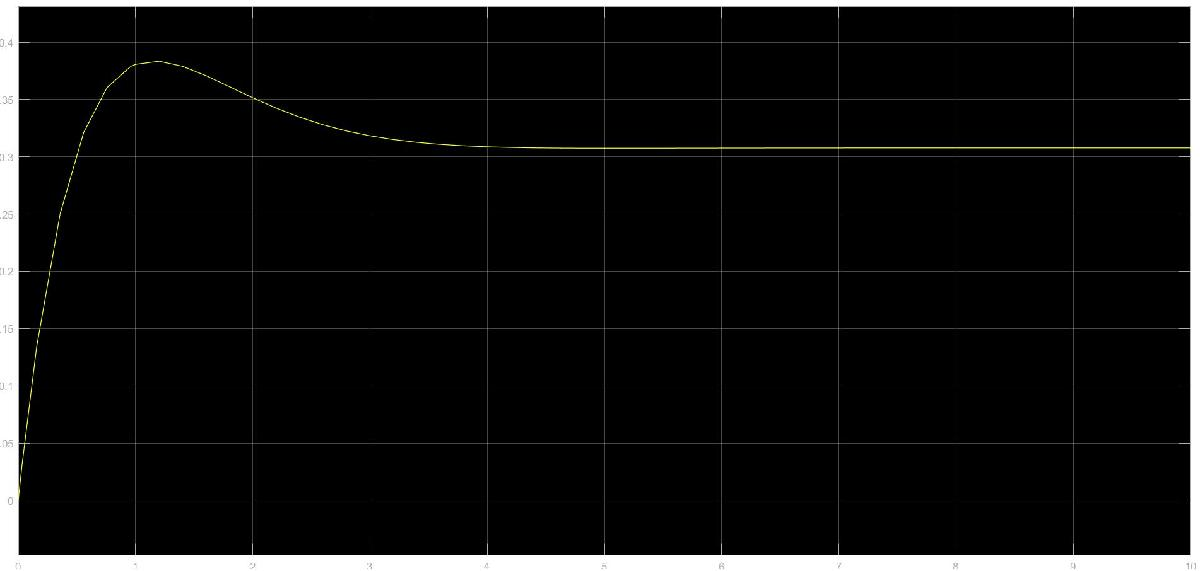

Insulin Level

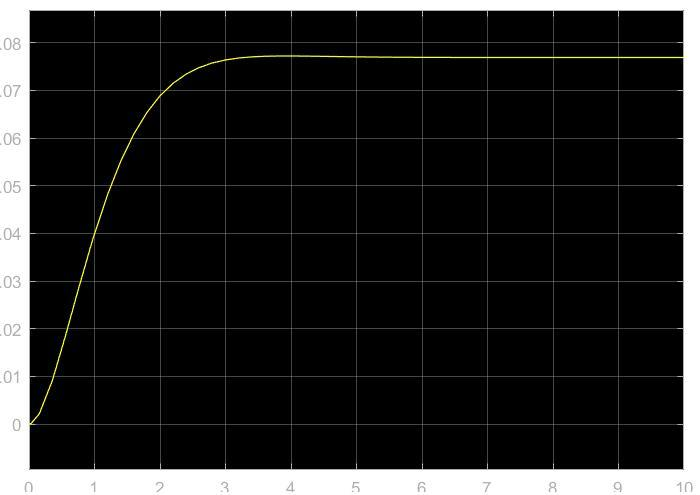

We can see the graphs resemble the data taken previously in part 1.

Model 2: Glucose Level

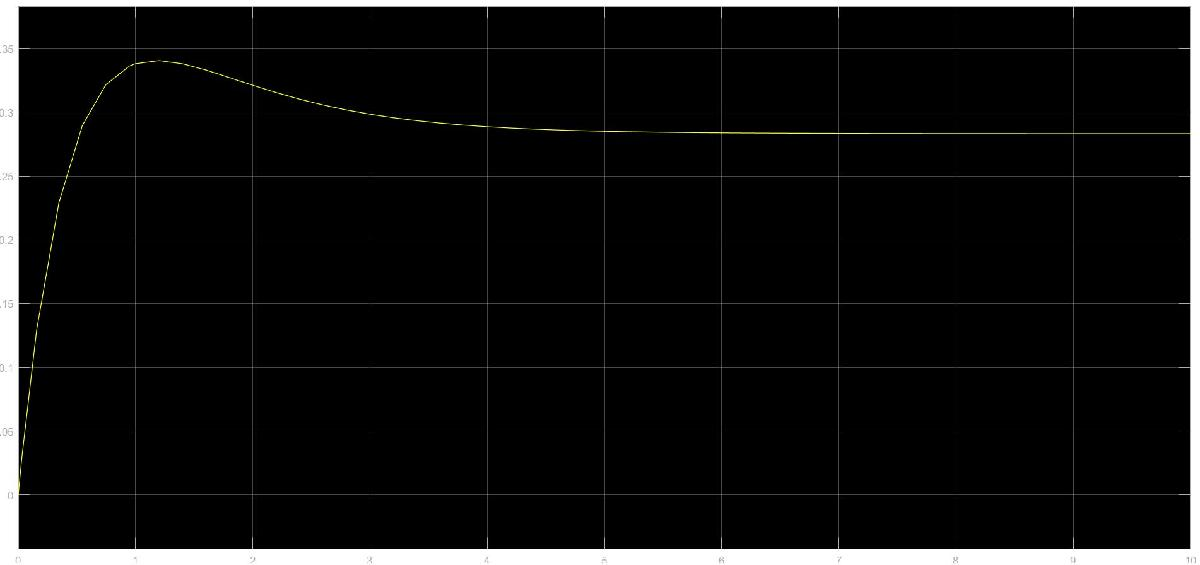

Insulin Level

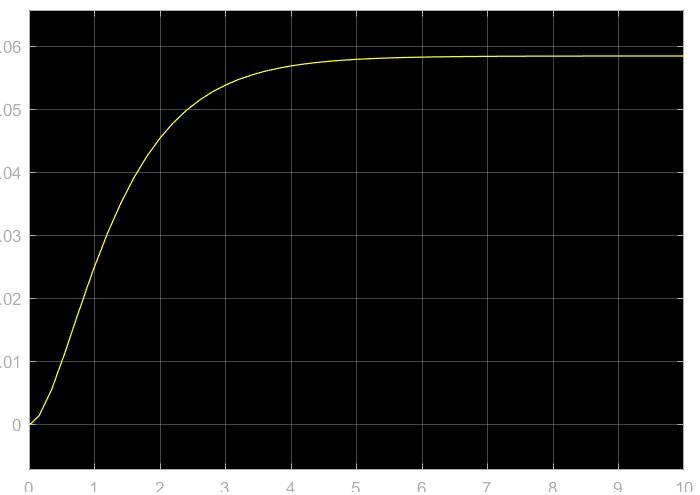

Both the insulin and glucose levels have dropped due to the different co oefficients used in this case. 

**B(t) = 0.1 U/kg/h**

**Normal:**

Glucose Level

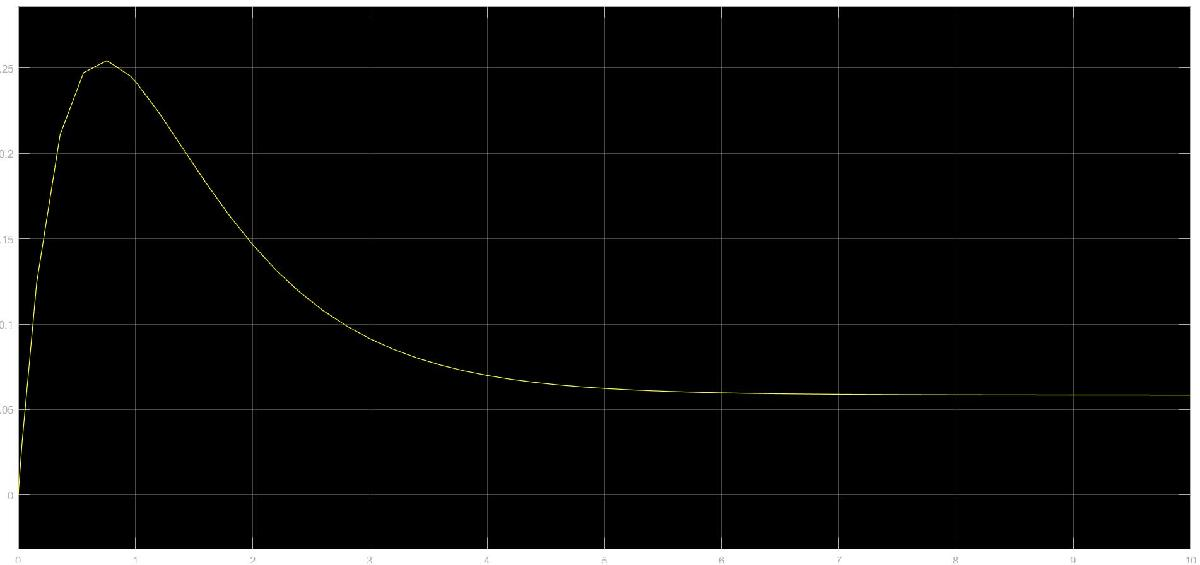

Insulin Level

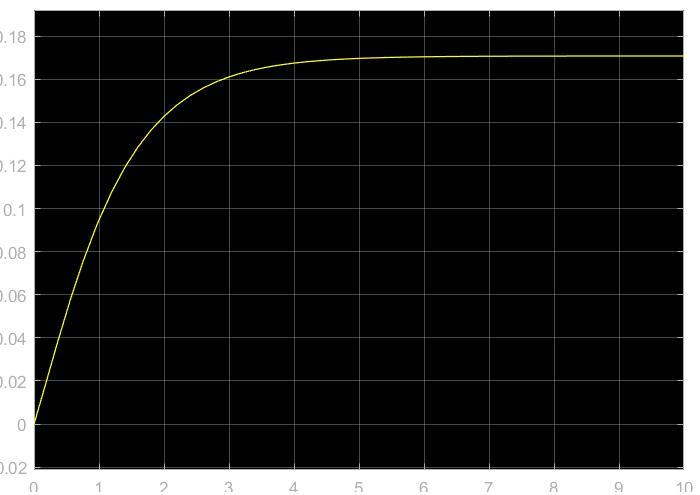

**Diabetic:**

Glusoce Level:

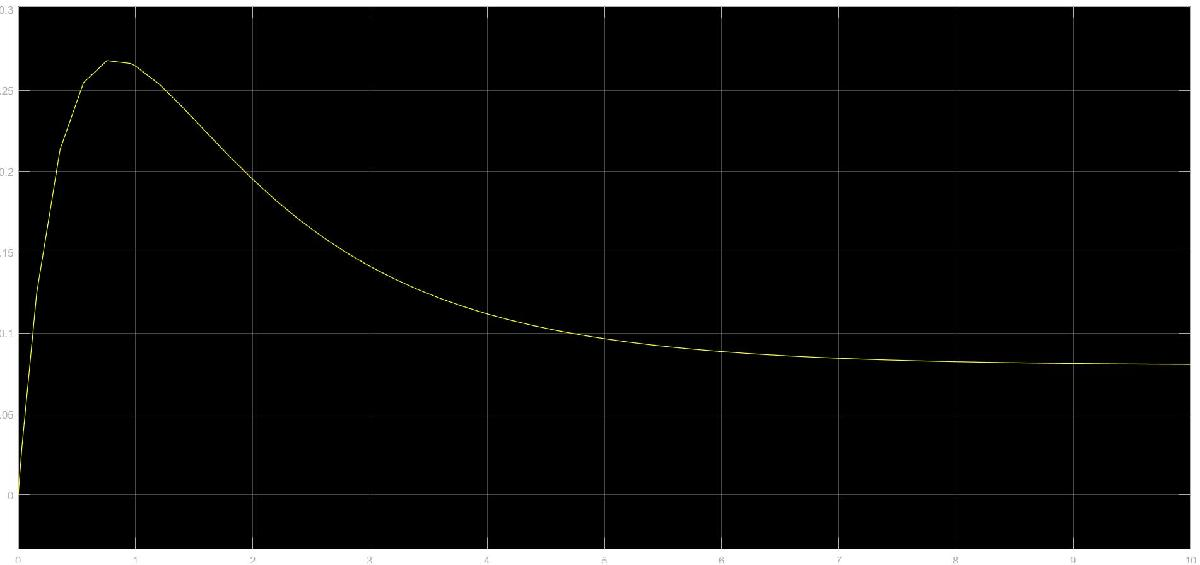

Insulin Level:

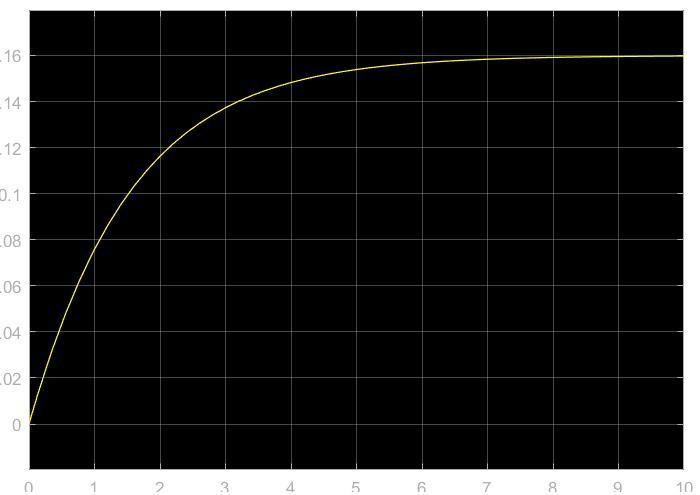

**Q2**

Plasma Iodine

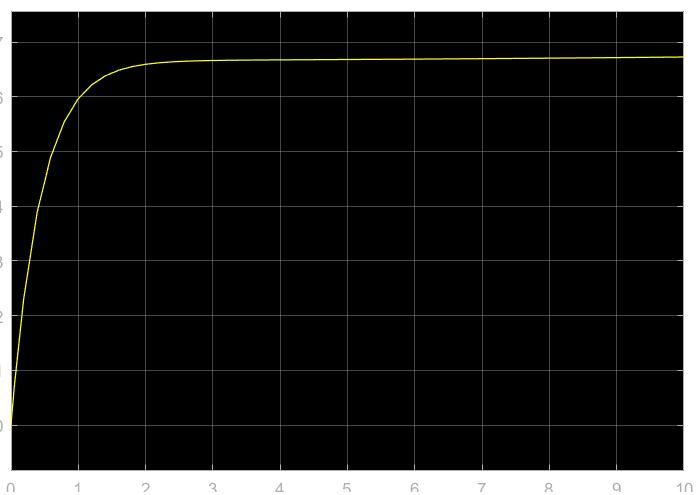

Gland Iodine

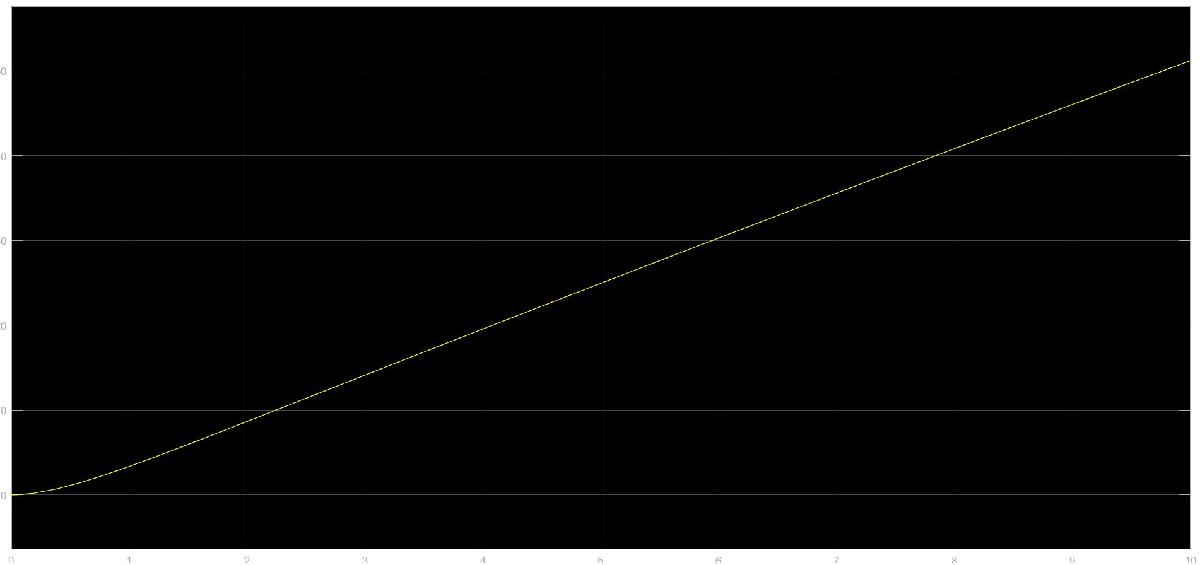

Hormonal Iodine

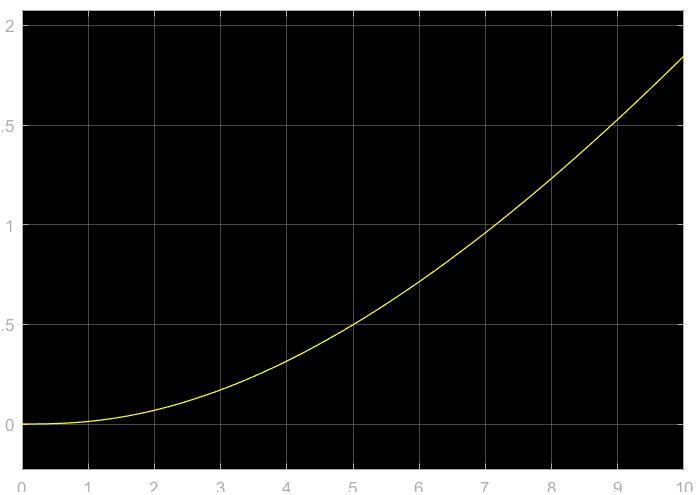

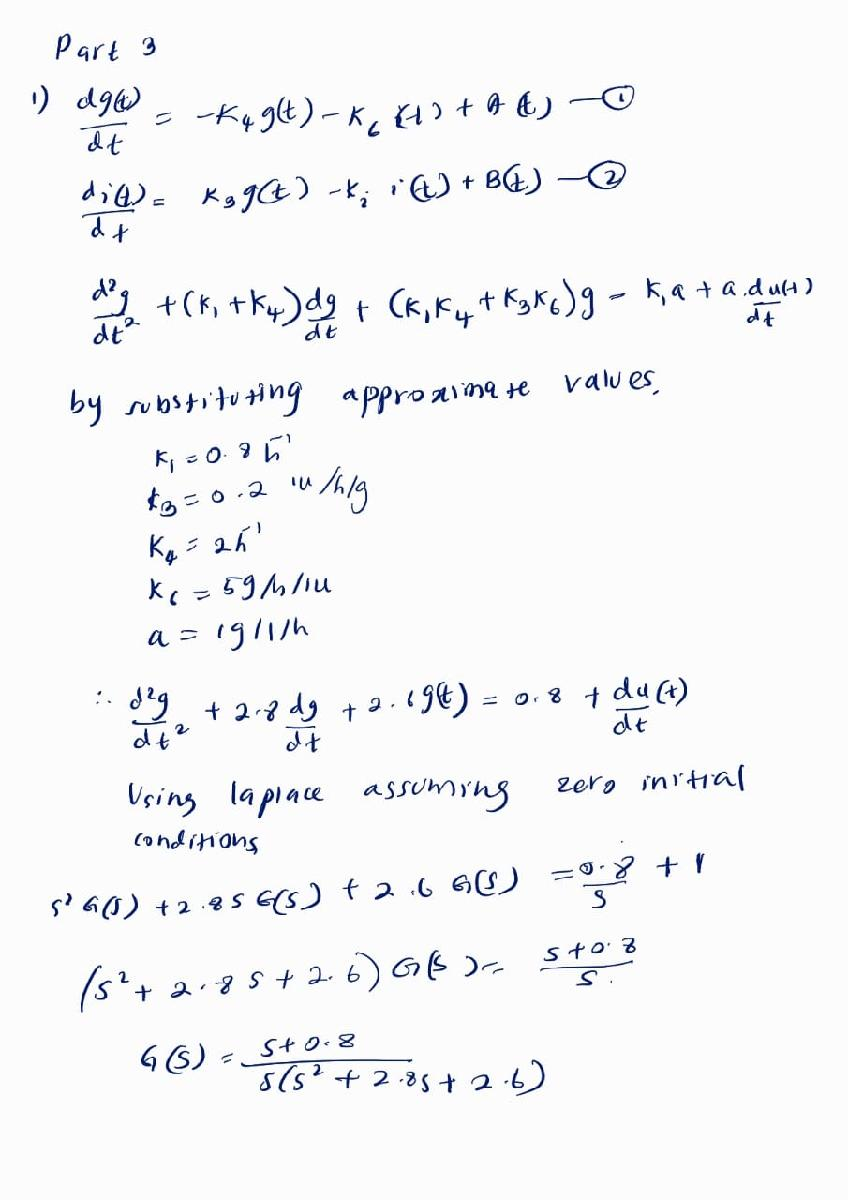

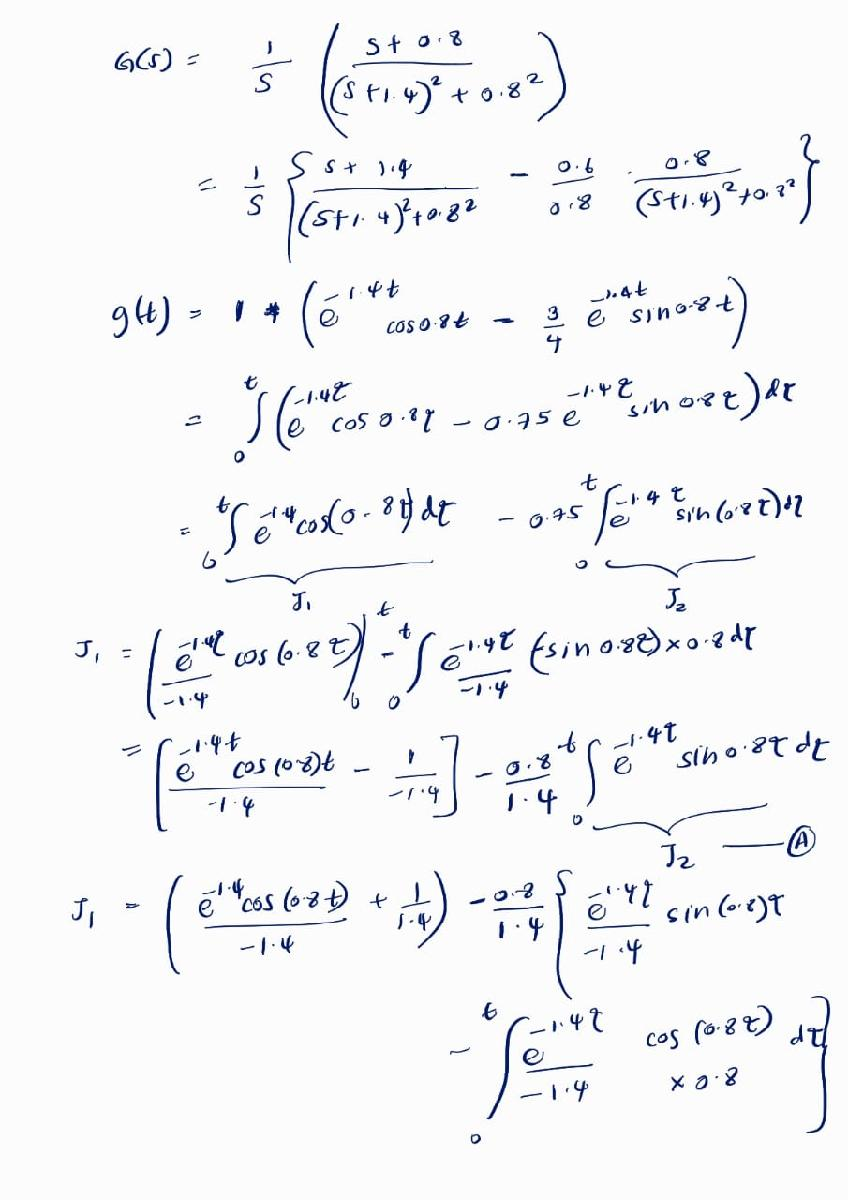

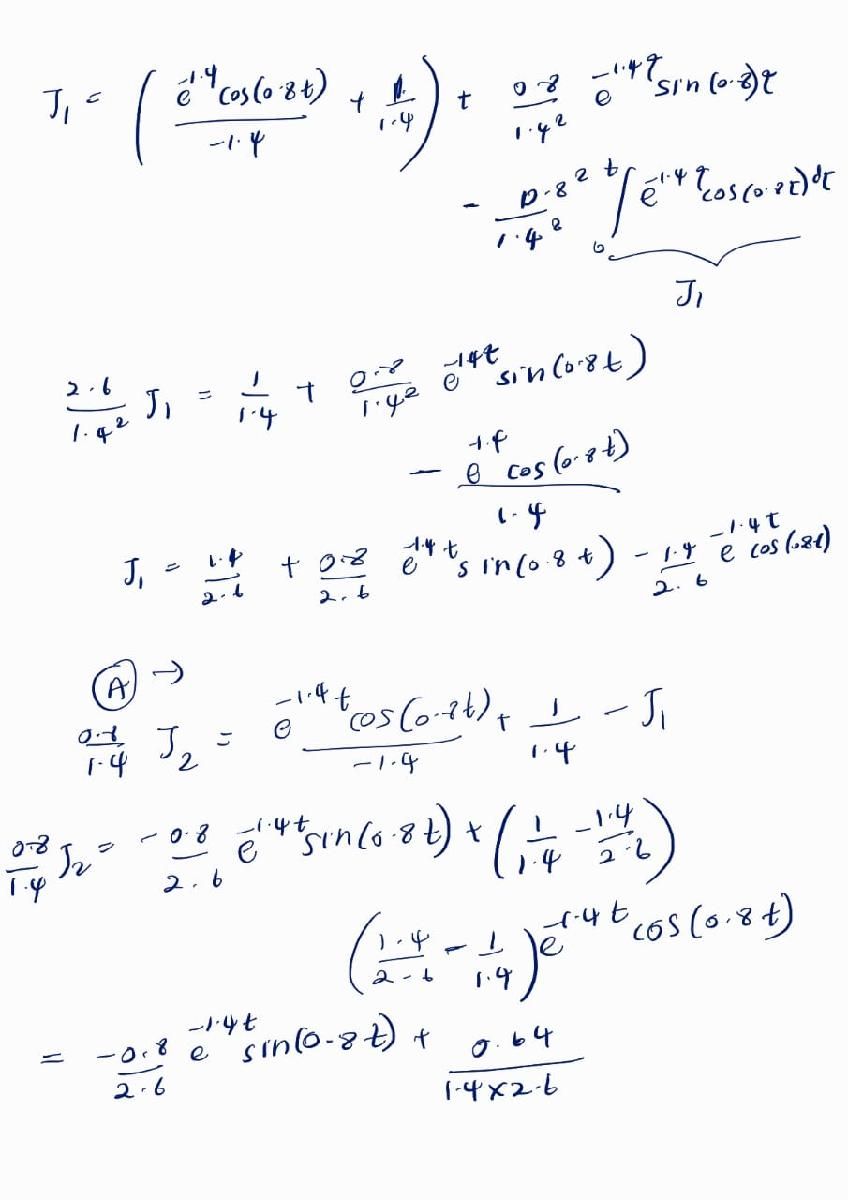

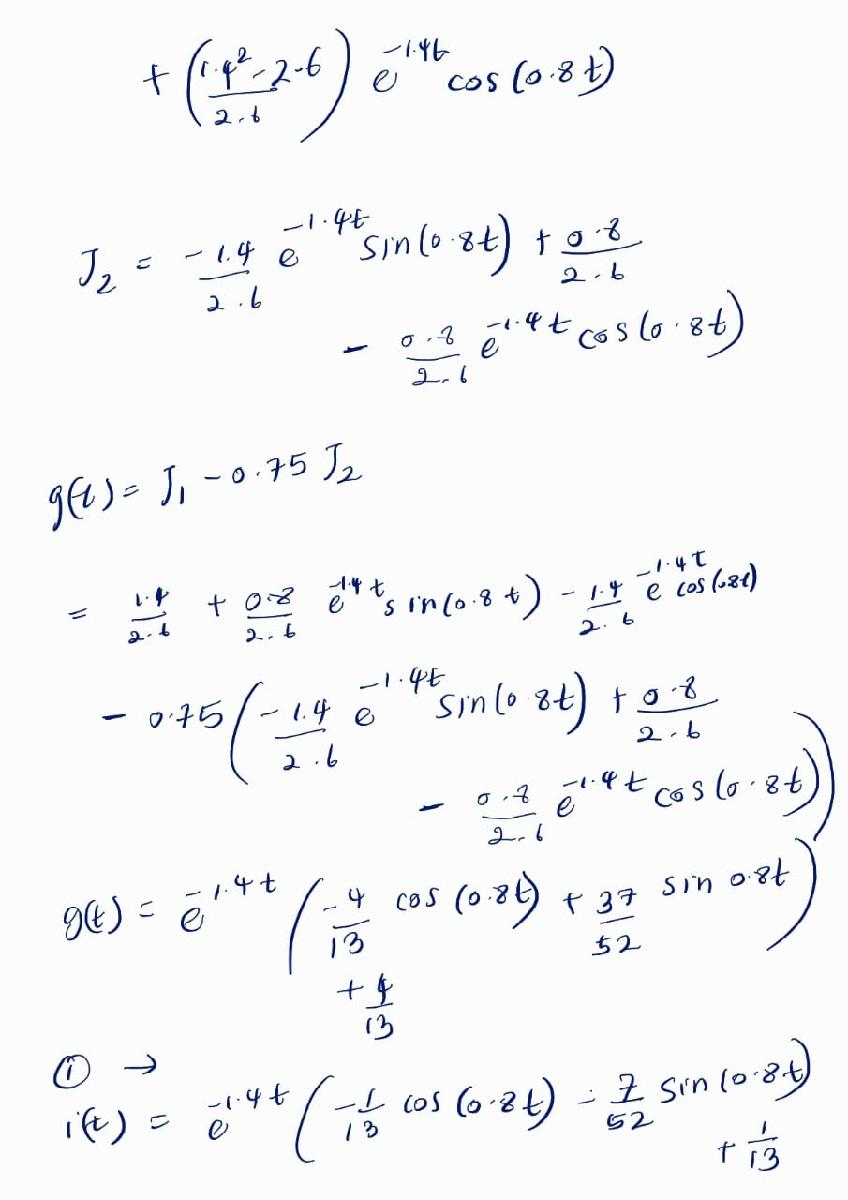

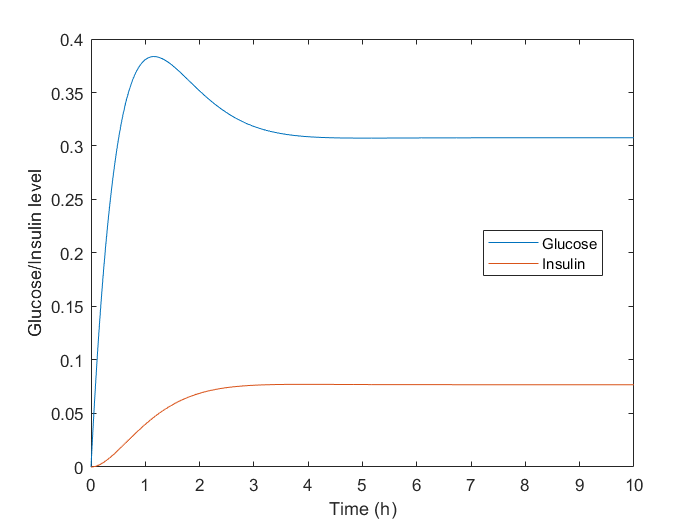

t = 0:0.01:10;
g_t = (exp((-1.4).*t)).*(-(4/13)*cos((0.8).*t) + (37/52)*sin((0.8).*t)) + 4/13; 
i_t = (exp((-1.4).*t)).*(-(1/13)*cos((0.8).*t) - (7/52)*sin((0.8).*t)) + 1/13;
plot(t,g_t,t,i_t);
legend ('Glucose','Insulin',"Location","best")
xlabel ('Time (h)');
ylabel ('Glucose/Insulin level');

## Q2)

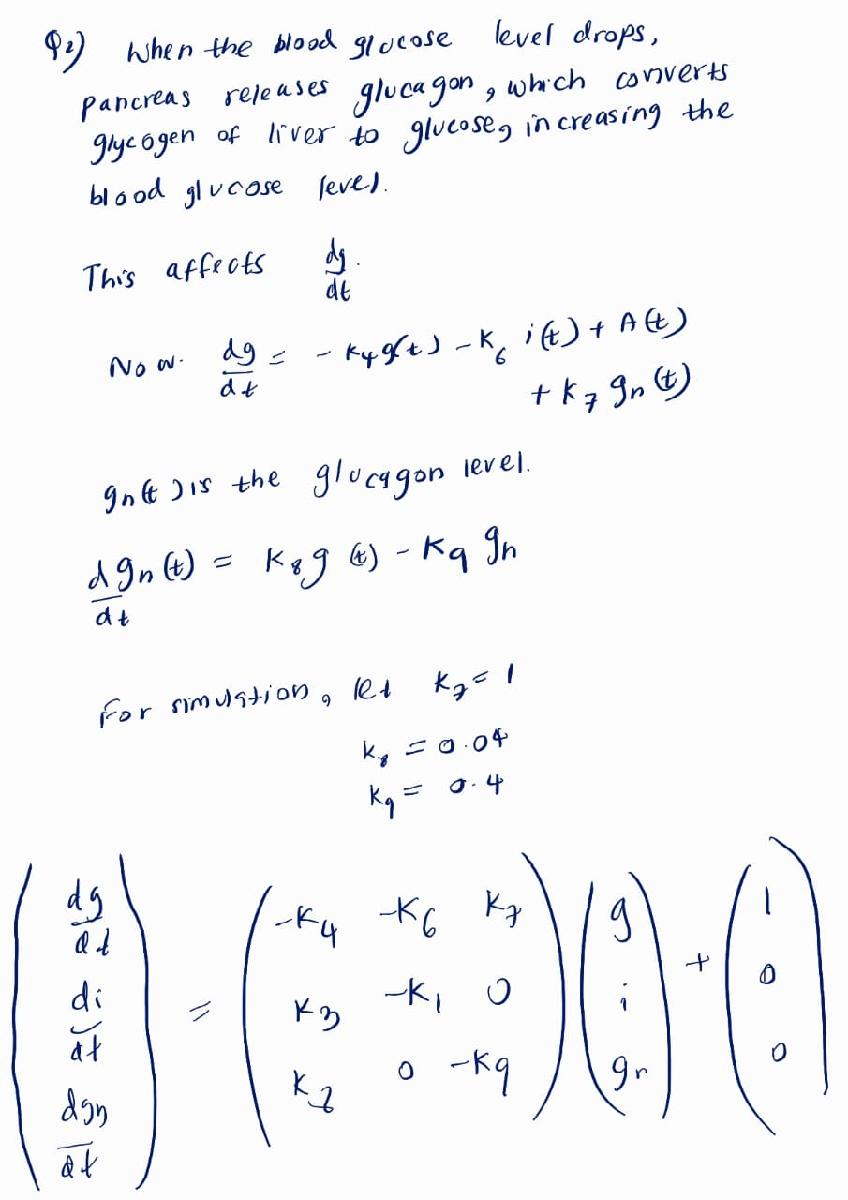

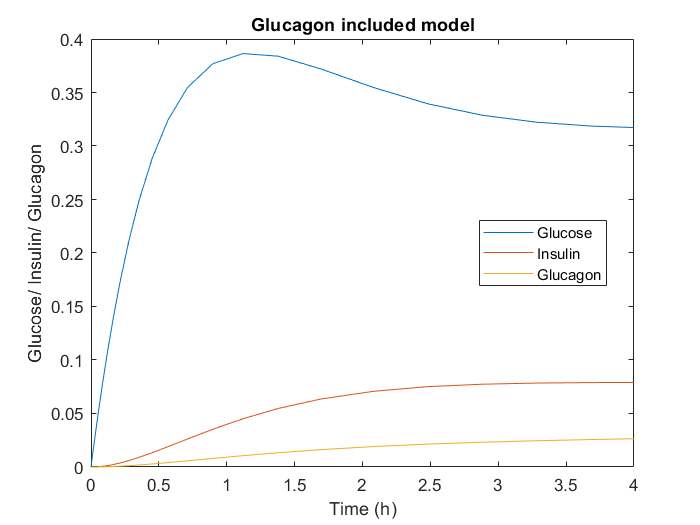

[t,y] = ode23('Glucagon_model',[0, 4],[0, 0, 0] );
plot(t,y);
legend('Glucose','Insulin','Glucagon',"Location","best");
xlabel('Time (h)');
ylabel('Glucose/ Insulin/ Glucagon');
title('Glucagon included model');

The glucagon becomes active, only when there is a drop in the glucose level. We can see that the glucagon gets activated after the insulin action takes place, and gets to a equlibrium state with Insulin. There is a slight delay in this, as it takes a bit of time to detect the drop of glucose level. With that we can conclude that the model is correct regarding the action of glucagon. 